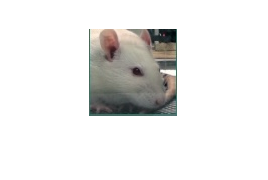

clc; clear; close all

img=imread('IMG_5845 2.jpg');
imshow(img)

I=rgb2gray(img);

%I_sobel=edge(I,'Sobel');
[I_test, threshold]=edge(I,'Canny');

Threshold (adjust slider that isolates the eyes the most)

threshold

threshold =     0.0875    0.2188


I_edge=edge(I,'Canny',2.8* threshold);



Eye isolation

se90=strel('line',3,90);
se0=strel('line',3,0);
I_dilate=imdilate(I_edge,[se90 se0]);

I_fill=imfill(I_dilate,'holes');

I_erode=imerode(I_fill,[se90 se0]);
I_erode=imerode(I_erode,[se90 se0])

I_erode = 87×88 logical array
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

I_clear=imclearborder(I_erode);

I_final=labeloverlay(img,I_clear)

I_final = 87×88×3 uint8 array
I_final(:,:,1) =

    78   217   233   248   243   247   245   248   243   253   244   249   250   247   245   217   200   196   194   192   195   194   194   196   214   250   253   248   240   240   240   239   238   245   242   238   229   194   155   139   136   140   134   133   130   131   129   126   127   132   136   144   148   156   152   150   159   143    83    48    41    53    61    33    27    75   123   129   122    84    20    22    19    23    16    15    28    29    25    32    28    20    17    23    22    15     5    69
    79   219   239   242   244   245   249   245   250   246   253   247   241   226   201   196   193   192   190   188   189   187   186   186   191   216   247   250   244   239   241   242   241   245   248   245   244   242   219   187   161   154   139   135   133   133   131   132   133   136   140   142   146   153   146   144   152   159   120    56    42    42    54    38    39    69   125   130   129    88   

Final images

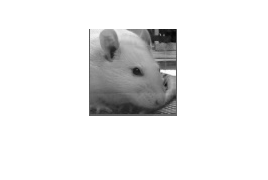

imshow(I)

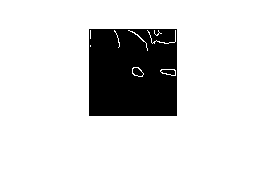

imshow(I_edge)

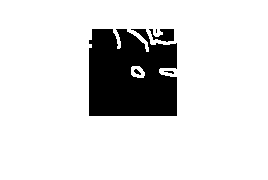


imshow(I_dilate)

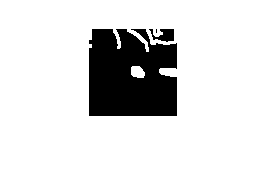

imshow(I_fill)

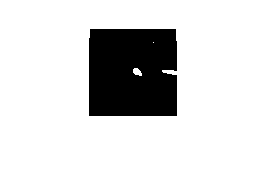

imshow(I_erode)

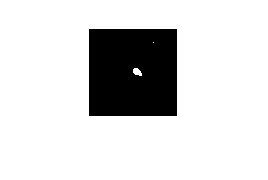

imshow(I_clear)

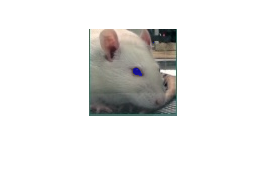


imshow(I_final)

Calculation of eye's area (biggest on image)

region=regionprops(I_clear)

region = 2×1 struct array with fields:
    Area
    Centroid
    BoundingBox


Area=[region.Area]

Area =     51     1


eye=Area(find(Area==max(Area)))

eye = 51